**Support Vector Machines**

support vector machines (SVMs) to build a spam classifier using a Gaussian kernel with SVM.

clear
dir


.                          ex6data3.mat               spamTest.mat               
..                         featureNormalize.m         spamTrain.mat              
SVM.mlx                    gaussianKernel.m           submit.m                   
dataset3Params.m           getVocabList.m             svmPredict.m               
diabetes2D.csv             lib                        svmTrain.m                 
emailFeatures.m            linearKernel.m             token.mat                  
emailSample1.txt           plotData.m                 visualizeBoundary.m        
emailSample2.txt           porterStemmer.m            visualizeBoundaryLinear.m  
ex6.mlx                    processEmail.m             vocab.txt                  
ex6_companion.mlx          readFile.m                 
ex6data1.mat               spamSample1.txt            
ex6data2.mat               spamSample2.txt            



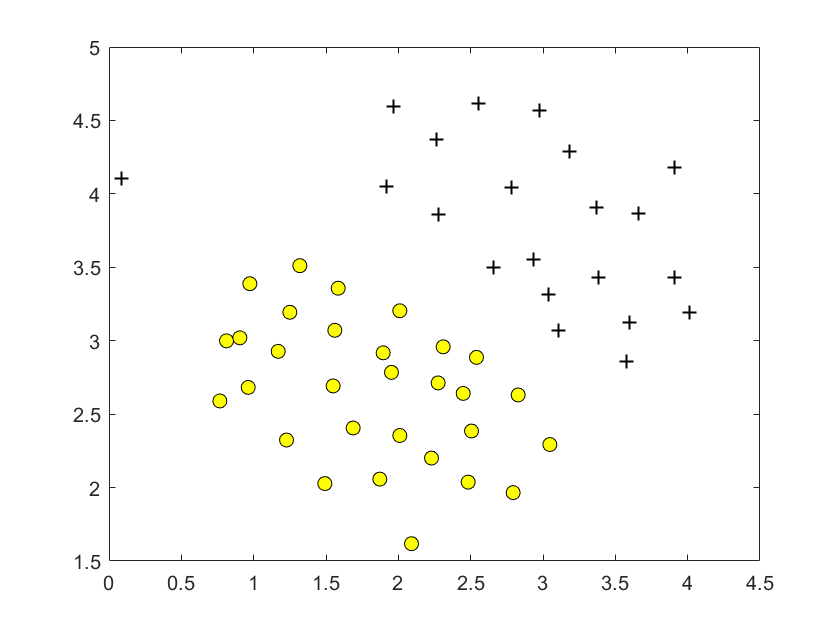

% Load from ex6data1: 
% You will have X, y in your environment
load('ex6data1.mat');
% Trying with diabetice data
%data = csvread('diabetes2D.csv',1,0);
%X = data(:, [1, 2]); 
%y = data(:, 3);
%X = featureNormalize(X);
% Plot training data
plotData(X, y);

you will try using different values of the  parameter with SVMs.

**Note:** Most SVM software packages (including `svmTrain.m`) automatically add the extra feature $x_0 = 1$ for you and automatically take care of learning the intercept term $\theta_0$. So when passing your training data to the SVM software, there is no need to add this extra feature $x_0 = 1$ yourself. In particular, in MATLAB your code should be working with training examples $x\in\mathbb{R}^n$ (rather than $x\in\mathbb{R}^{n+1}$) for example, in the first example dataset $x\in\mathbb{R}^2.$

**SVM with Linear Kernels **

%C = 10;
C = 10; sigma = 0.1;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);


Training ......................................................................
............................................ Done! 



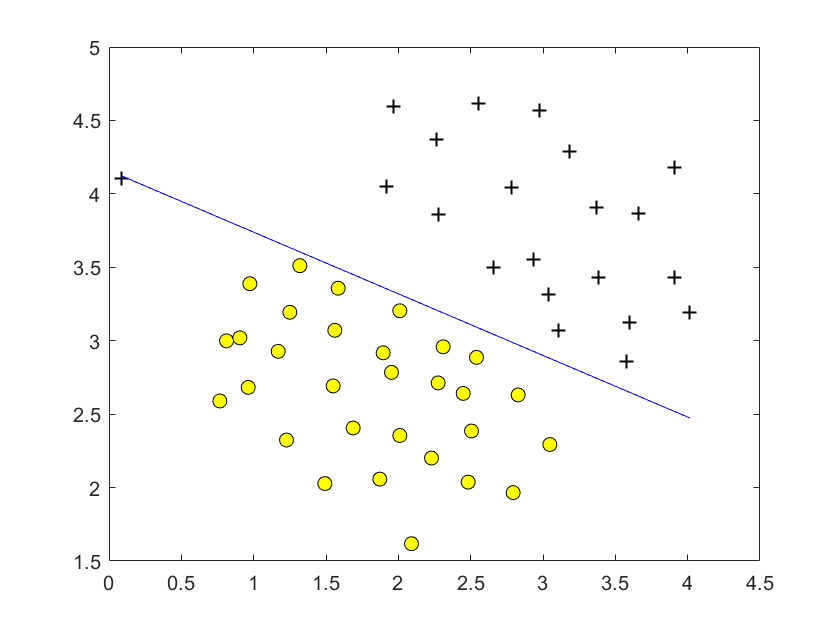

%model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 
visualizeBoundaryLinear(X, y, model);

**SVM with gaussian kernels**

SVMs with Gaussian kernels on datasets that are not linearly separable

x1 = [1 2 1]; x2 = [0 4 -1]; 
sigma = 16;
sim = gaussianKernel(x1, x2, sigma);
fprintf('Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = %f : \n\t%g\n', sigma, sim);

Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = 16.000000 : 
	0.982575


Trying with data set

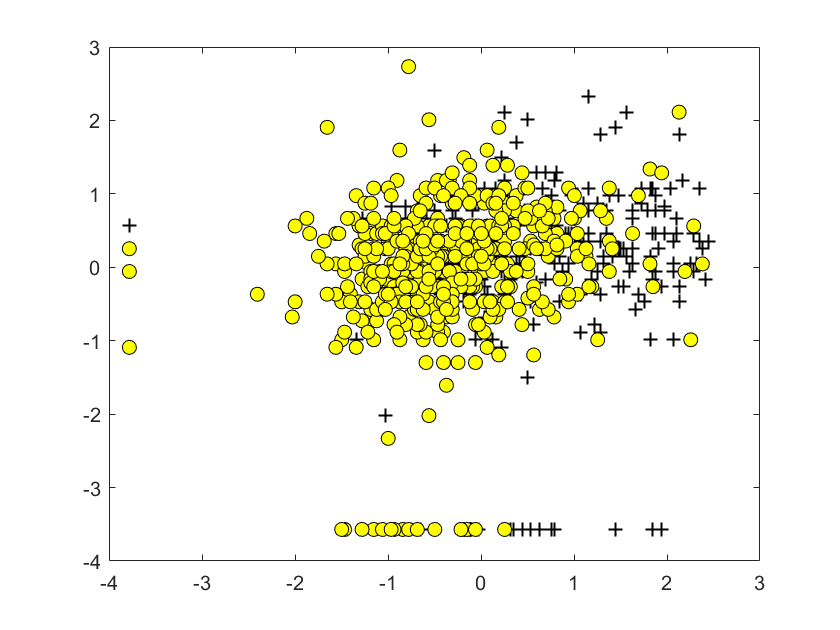

% Load from ex6data2: 
% You will have X, y in your environment
%load('ex6data2.mat');
data = csvread('diabetes2D.csv',1,0);
X = data(:, [1, 2]); 
y = data(:, 3);
X = featureNormalize(X);
% Plot training data
plotData(X, y);   

% SVM Parameters
C = 0.5; sigma = 1;
% We set the tolerance and max_passes lower here so that the code will run faster. However, in practice, 
% you will want to run the training to convergence.
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
....................................................................... Done! 



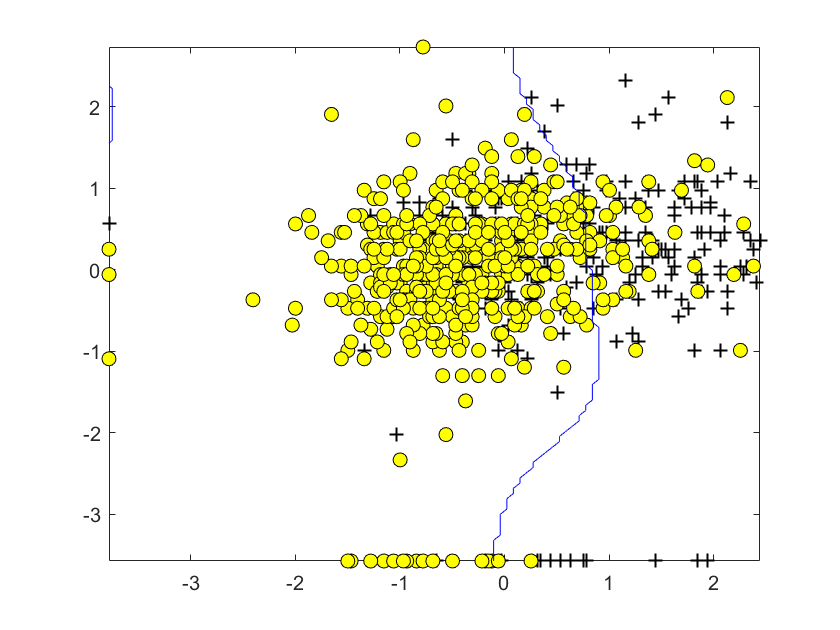

visualizeBoundary(X, y, model);

**Spam Classification**

Preprocessing emails

%% Initialization
clear;
% Extract Features
file_contents = readFile('emailSample1.txt');
word_indices  = processEmail(file_contents);


==== Processed Email ====

anyon know how much it cost to host a web portal well it depend on how mani 
visitor you re expect thi can be anywher from less than number buck a month 
to a coupl of dollarnumb you should checkout httpaddr or perhap amazon ecnumb 
if your run someth big to unsubscrib yourself from thi mail list send an 
email to emailaddr 



% Print Stats
disp(word_indices);

          86
         916
         794
        1077
         883
         370
        1699
         790
        1822
        1831
         883
         431
        1171
         794
        1002
        1893
        1364
         592
        1676
         238
         162
          89
         688
         945
        1663
        1120
        1062
        1699
         375
        1162
         479
        1893
        1510
         799
        1182
        1237
         810
        1895
        1440
        1547
         181
        1699
        1758
        1896
         688
        1676
         992
         961
        1477
          71
         530
        1699
         531



Extracting features from emails

% Extract Features
features = emailFeatures(word_indices);
% Print Stats
fprintf('Length of feature vector: %d\n', length(features));

Length of feature vector: 1899


fprintf('Number of non-zero entries: %d\n', sum(features > 0));

Number of non-zero entries: 45


Training SVM for spam classification

% Load the Spam Email dataset
% You will have X, y in your environment
load('spamTrain.mat');
C = 0.1;
model = svmTrain(X, y, C, @linearKernel);


Training ......................................................................
...............................................................................
...............................................................................
............................... Done! 



%Sigma = 0.5;
%model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 

Prediction and accuracy

p = svmPredict(model, X);
fprintf('Training Accuracy: %f\n', mean(double(p == y)) * 100);

Training Accuracy: 99.825000


% Load the test dataset
% You will have Xtest, ytest in your environment

Test data

load('spamTest.mat');
p = svmPredict(model, Xtest);
fprintf('Test Accuracy: %f\n', mean(double(p == ytest)) * 100);

Test Accuracy: 98.600000


**Top predictors for spam**

% Sort the weights and obtin the vocabulary list
[weight, idx] = sort(model.w, 'descend');
vocabList = getVocabList();
for i = 1:15
    if i == 1
        fprintf('Top predictors of spam: \n');
    end
    fprintf('%-15s (%f) \n', vocabList{idx(i)}, weight(i));
end

Top predictors of spam: 


our             (0.497913) 
click           (0.469698) 
remov           (0.421233) 
guarante        (0.386510) 
visit           (0.373096) 
basenumb        (0.348715) 
dollar          (0.323664) 
will            (0.267457) 
price           (0.266110) 
most            (0.263020) 
pleas           (0.261774) 
nbsp            (0.250387) 
lo              (0.247430) 
ga              (0.244044) 
hour            (0.240035) 
